# Step 1: label the training image pixel by pixel

In this step, we aim to label the training image pixel-by-pixel with one of the three labels: 1-background; 2-monolayer; 3-multilayer.

Since each image contains millions of pixels, it is a formidable job to label them one by one. Here we come up with proper superpixelization and clustering method to greatly reduce the work load and facilitate the labeling process. 

## 1) Configure the training data path and load image files

Examples of training image is in folder: /Train_example/images.

The training data are optical images of graphene/graphite flakes taken under various laboratory conditions.

Labeled images and image labels will be stored at /Train_example/labeled_images, and /Train_example/labels respectively.

Before running the program, please remember to add the current directory to path.

dataPath = fullfile(pwd, 'Train_example');

imageFolder = 'images';
labeledImageFolder = 'labeled_images';
labelFolder = 'labels';
imageExtensions = {'.jpg'};

configure(pwd);
imagePath = fullfile(dataPath, imageFolder);
labeledImagePath = fullfile(dataPath, labeledImageFolder);
labelPath = fullfile(dataPath, labelFolder);

Folders are created for the labeled images and corresponding labels (if not exist).

if ~exist(labeledImagePath, 'dir')
    mkdir(labeledImagePath);
end

if ~exist(labelPath, 'dir')
    mkdir(labelPath);
end

Now we need to create an image list from the folder: /Train_example/images. And then we read the image file one by one.

SCALING_FACTOR = 0.1; % the scaling factor to resize the image. Default:0.1

% create image list for images inside the folder
imageList = {};
for iter = 1:length(imageExtensions)
    imageList = [imageList;...
        getAllFiles(imagePath, sprintf('*%s',imageExtensions{iter}), 0)];
end

numberOfImages = length(imageList);
% pick up one image randomly from the list
imageID = ceil(rand()*numberOfImages);
% or you can choose one image from the image list
% imageID = 1  % default = 1, then 1st image in the image list is chosen

% read the image file with the chosen imageID
imageFilename = imageList{imageID};
imageOriginal = imread(fullfile(imagePath,imageFilename)); 

Let's show the image.

figure(1); clf(1);
figure(1);
imshow(imageOriginal); % show original image

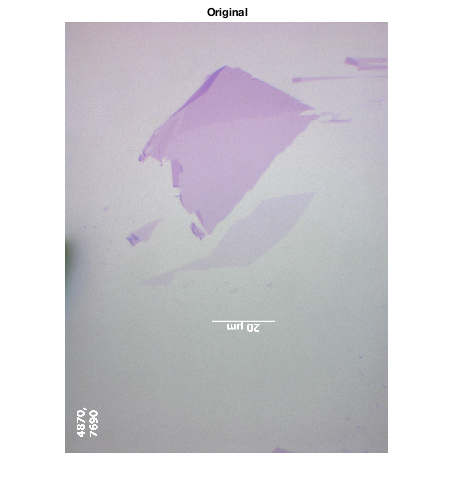

title('Original');

This is the original image. We can scale the image by 0.1 to reduce the pixels and also normalized the image to insure a similar color distribution in different images.

Here we used the median pixel color to approximate the background color. The images were firstly projected from the RGB color space to the L*a*b color space, in which L, a and b indicate respectively the lightness and the components of green-red and blue-yellow. The normalization transformation can be expressed as L = 50L/L_ref, a = a-a_ref, and b = b-b_ref. The color distributions of each classes become very similar after normalization.

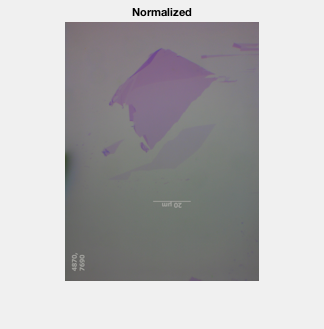

% resize the image
image = imresize(imageOriginal,SCALING_FACTOR); 
% normalize the image
imageNormed = normalize(image);

% show normalized image
figure(2); clf(2);
figure(2);
imshow(imageNormed); 
title('Normalized');

## 2) SLIC superpixelization

Superpixel is a clustering of neighboring pixels with perceptually meaningful similarities. The SLIC method adapts the K-means clustering algorithm into the superpixelization problems. The distance used in the K-means clustering algorithm is the distance in the combinational pixel position space (x,y) and the L*a*b color space (l,a,b) with a specified scaling factor. To eliminate the searching effort, the algorithm also confined the regions of k-means searching to a limited range instead of the entire image as in the standard K-means clustering algorithm. In order to make sure the superpixelization is able to capture finest features of the images, we increased the total number of superpixels and decreased the minimum superpixel diameters.

More details can be found in http://www.peterkovesi.com/matlabfns/#segmentation. 

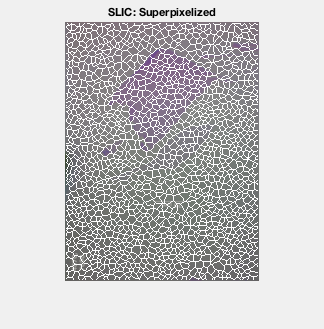

% superpixelization parameters
SP_PARS = struct();
SP_PARS.NUMBER_SP = 2500;
SP_PARS.WF = 1; % weighting factor between color and spatial differences
SP_PARS.MIN_SP = 1; % smallest superpixel size
SP_PARS.COLOR_OPT = 'median'; % color option: 'median' or 'mean'

[imageLabelsSuperpixel, Am, C] = ...
    slic(imageNormed, SP_PARS.NUMBER_SP, SP_PARS.WF, ...
    SP_PARS.MIN_SP, SP_PARS.COLOR_OPT); % superpixelize

figure(3); clf(3);
figure(3);
imshow(drawregionboundaries(imageLabelsSuperpixel, imageNormed,[255,255,255])); % show image
title('SLIC: Superpixelized');

## 3) DBSCAN clustering

As can be seen in the superpixelized image, the superpixel size is still too small to render meaningful labeling. 

It is requred to further combine the superpixels according to similarities and achieve the desired level of segmentations of the images. Although the color distributions of each desired cluster may be tight and regular, the spans in the pixel space of the desired clusters may be in very ireggular shape, and thus could not be determined by simply thresholding a distance function. This is when the spectral clustering comes into place. Here we adapted the density based spatial clustering of applications with noise (DBSCAN) method and used the medians of the scaled combination of the L*a*b color space and the pixel space distances as the measure of weigths of the edges between two superpixel vertices. 

One hyperparameter that is very critical in this algorithm is the threshold value that indicates the maximum distances of two superpixels that can be combined into a single cluster. 

Because the color-pixel distance between the background and the monolayer regions are usually substantially smaller than the variations within the background and/or the multilayer regions, a single threshold value would either incorrectly combined the monolayer regions into the background regions, or segment the background and the multilayer regions into too many clusters.

Here we use two threshold parameters to properly differentiate the difference between graphite/background and graphene/background.

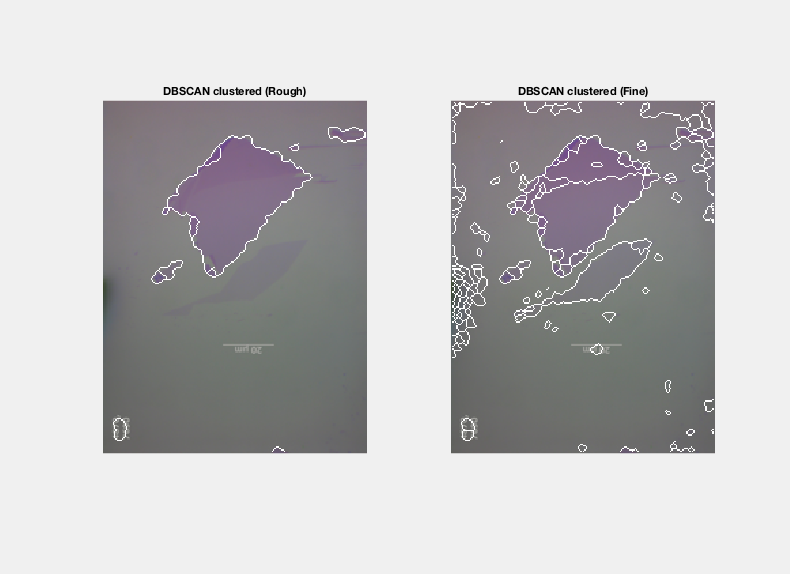

% clustering parameters
CL_PARS = struct();
CL_PARS.TOL_ROUGH = 5;
CL_PARS.TOL_FINE = 0.8;   %Controls the fine threshold parameter, may need to change

imageLabelsCluster = spdbscan(imageLabelsSuperpixel, C, Am, ...
    CL_PARS.TOL_ROUGH ); % cluster-rough, to differentiate more prominent features
imageLabelsCluster_2 =spdbscan(imageLabelsSuperpixel, C, Am, ...
    CL_PARS.TOL_FINE); % cluster-fine, to differentiate more subtle features

imageWithClusterBoundaries = ...
    drawregionboundaries(imageLabelsCluster, imageNormed,[255,255,255]);

imageWithClusterBoundaries_2 = ...
    drawregionboundaries(imageLabelsCluster_2, imageNormed,[255,255,255]);

figure(4); subplot(1,2,1);
imshow(imageWithClusterBoundaries);% show image
title('DBSCAN clustered (Rough)');

figure(4); subplot(1,2,2);
imshow(imageWithClusterBoundaries_2);% show image
title('DBSCAN clustered (Fine)');

We can plot the result from "cluster-rough" and "cluster-fine" together, with blue boundaries denote the boundaries found by "cluster-rough" and white boundaries denote the boundaries found by "cluster-fine".

We aim to assign one of the three labels to each pixels: 1-background; 2-monolayer; 3-multilayer.

% cluster-rough
[backgroundLabel, backgroundMask] = findBackgroundCluster(imageLabelsCluster);
% background and multi-layer are initially labeled using cluster-rough result 
% monolayer label will be corrected later
bgMask = backgroundMask;
multiMask = ~backgroundMask;
monoMask = logical(size(backgroundMask)); % empty mask; label place holder
imageLabelsFinal = masks2Labels({bgMask, monoMask, multiMask});

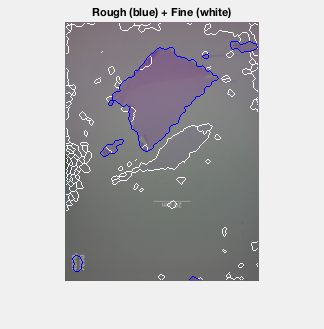


% cluster-fine
[backgroundLabel_2, backgroundMask_2] = findBackgroundCluster(imageLabelsCluster_2);
imageClustersFinal = combineMaskedLabels(...
    {imageLabelsCluster_2, imageLabelsCluster_2, imageLabelsCluster},...
    {bgMask, monoMask, multiMask});

imageWithClusterBoundaries = ...
    drawregionboundaries(imageClustersFinal, imageNormed,[255,255,255]);
imageWithClusterBoundaries = ...
    drawregionboundaries(monoMask, imageWithClusterBoundaries,[0,255,0]);
imageWithClusterBoundaries = ...
    drawregionboundaries(multiMask, imageWithClusterBoundaries,[0,0,255]);

figure(5); clf(5);
figure(5);
imshow(imageWithClusterBoundaries);% show image
title('Rough (blue) + Fine (white)');

## 4) Label assignment and manual correction

Now we see that "cluster-rough" generally can differentiate object with higher contrast, such as thick graphite flakes. However, it ignores the subtle difference between background and nano-materials. In contrast, "cluster-fine" can differentiate desired nano-materials but also pick up noise from the background. Neither of them are ideal for our purpose.

Frankly speaking, if there exist a simple algorithm to automatically identify and correctly label the nanomaterial, we won't resort to deep learning algorithm to help identify the nano-material.

What we have to do next is to adopt the "cluster-rough" as initial label framework, and manually correct the label for the monolayer region using what is discovered in "cluster-fine". 

For convenience, let's plot the boundaries produced by "cluster-fine" and overlay it with the original image. Meanwhile, each region is assigned with an unique number.

sizeImage = size(image);
sizeImageOriginal = size(imageOriginal);
sizeImageOriginal = sizeImageOriginal(1:2);


imageOriginalWithBoundaries = ...
    drawregionboundaries(imresize(imageClustersFinal,sizeImageOriginal, 'nearest'), imageOriginal,[255,255,255]);

imageOriginalWithBoundaries = ...
    drawregionboundaries(imresize(monoMask,sizeImageOriginal, 'nearest'), imageOriginalWithBoundaries,[0,255,0]);

imageOriginalWithBoundaries = ...
    drawregionboundaries(imresize(multiMask,sizeImageOriginal, 'nearest'), imageOriginalWithBoundaries,[0,0,255]);

imageClustersFinalWithLabels = labelClusters(...
    imresize(imageClustersFinal, sizeImageOriginal, 'nearest'), ...
    imageOriginalWithBoundaries, 'white');



figure(6); clf(6);
figure(6);
imshow(imageClustersFinalWithLabels);% show image

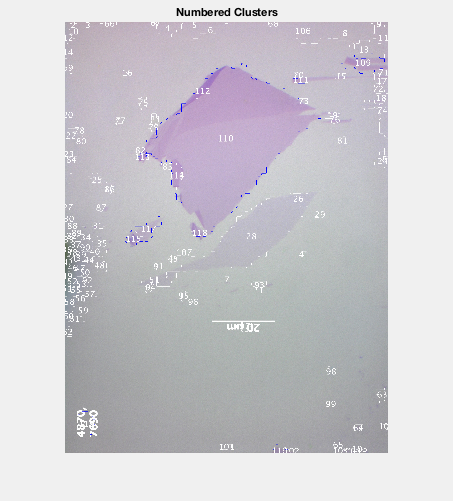

title('Numbered Clusters');

Now Matlab will ask you to identify the nano-material, which is the thinnest object in this image. Please type in the region number of the nano-material. It can be a vector if there are more than one regions. You can retry unlimited times if you are not satisfied with the result. The green boundary will show the labeled region for nano-materials.

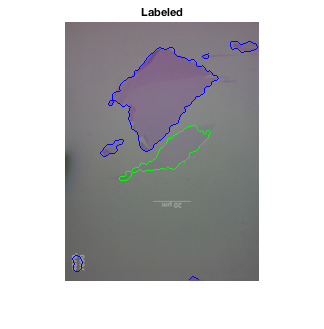

answer = 'y';
while ~strcmp(answer, 'n')
    message = 'Please input the cluster numbers for monolayers (as a row vector):';
    monoClusters = input(message);

    monoLabel = 2;

    imageLabelsCorrected = correctLabels(imageLabelsFinal, imageClustersFinal, [monoLabel], {monoClusters});

    imageWithLabelBoundaries = ...
        drawregionboundaries(imageLabelsCorrected==2, imageNormed,[0,255,0]);

    imageWithLabelBoundaries = ...
        drawregionboundaries(imageLabelsCorrected==3, ...
        imageWithLabelBoundaries,[0,0,255]);

    figure(7); 
    imshow(imageWithLabelBoundaries);% show image
    title('Labeled');
    
    message = 'Retry? (y/n)';
    answer = input(message,'s');
end

Save the labeled image and the labels in the designated folder.

message = 'Save? (y/n)';
answer = input(message,'s');

if strcmp(answer, 'y')
    
    % save the label matrix to .csv file
    [path, name, ext] = fileparts(imageFilename);
    labelFilename = sprintf('%s.csv',name);
    csvwrite(fullfile(labelPath,labelFilename),imageLabelsCorrected);
    
    % save the resized image
    imageResizedFilename = sprintf('%s_resized%s',name, ext);
    imwrite(image, fullfile(labelPath,imageResizedFilename));
    
    switchSaveFig = true;
    if switchSaveFig
        figFilename = sprintf('%s_analysis.jpg',name);
        saveas(7, fullfile(labelPath,figFilename));
    end
    
    % move the image to the "labeled image" folder
    movefile(fullfile(imagePath, imageFilename), labeledImagePath);

end